Figure 2B 

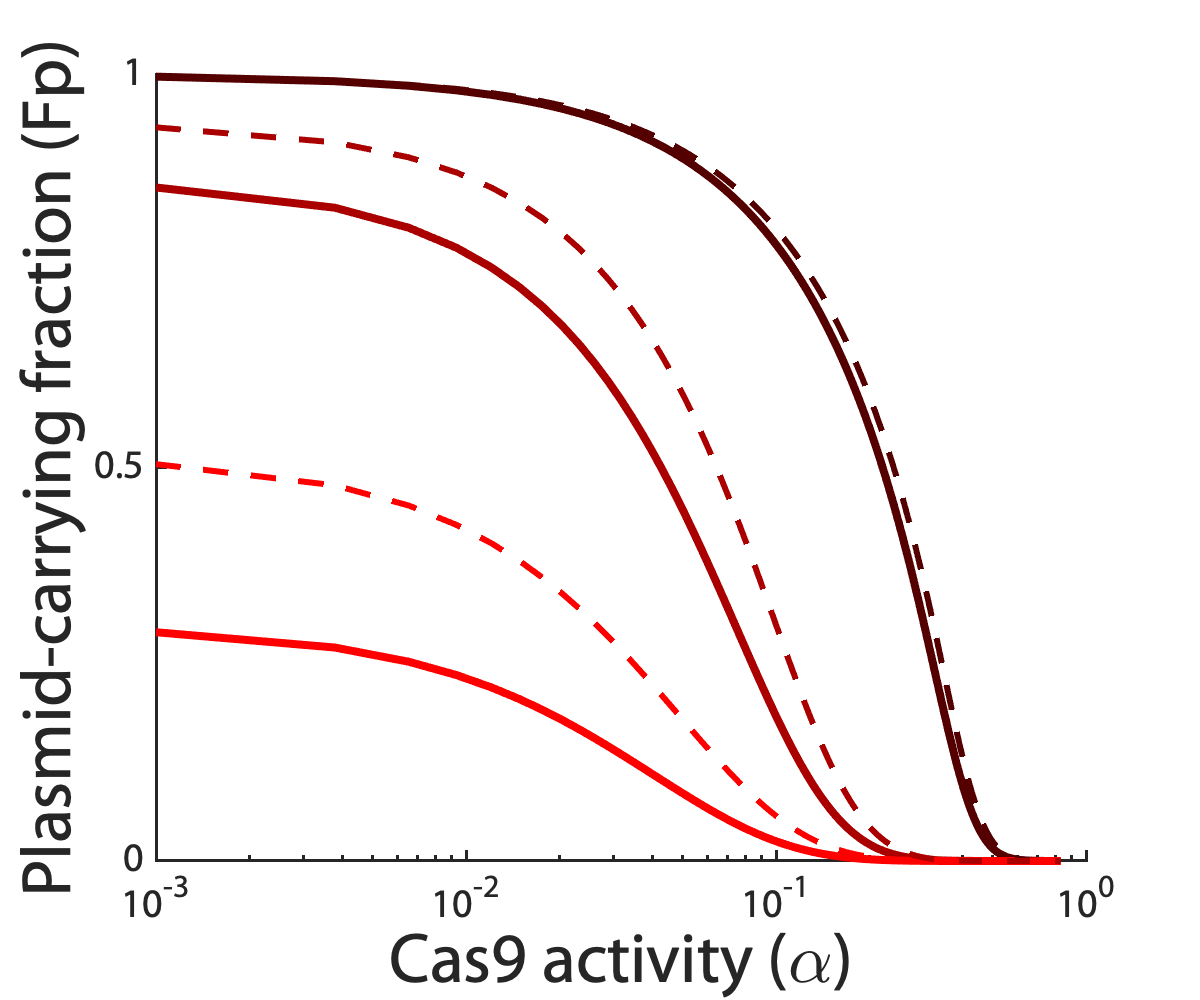

% plot Fp
% non-dimensionalized parameters used here
% non-dimensionalized by growth rate measured myself
% solid line => when no conjugation; dotted line => with conjugation;
global u_s u_p alpha eta delta gamma d

% define parameter values here
u_s = 1.15; u_p = 1.0; alpha = 0.83; delta = 0.17; eta = 0.05; gamma = 22; d = 1.9; 
alphas = linspace(0.001, 0.83, 300); 
deltas = [0.48, 0.12, 0];

% initialize arrays to save computed values
end_S = []; end_Sp = []; end_G = [];
S_final = zeros([length(deltas), length(alphas)]); 
Sp_final = zeros([length(deltas), length(alphas)]);

% color schemes
S_colors = [0, 0.1765, 0.2941; 0, 0.3059, 0.5098; 0, 0.4588, 0.7647;  ];
Sp_colors = [0.4549, 0.1725, 0.0510; 0.7059, 0.2667, 0.0784; 1.0, 0.3765, 0.1098;  ]; 
f_colors = hot(10);

% define time span and initial values
tmax = 24; tspan = [0 tmax]; y0 = [0.001; 0.001; 0]; 

% initialize figure so we can plot as we go 
ax = figure(); set(gcf, 'Position',  [10, 10, 600, 500]) ; hold on;

eta = 0; % first plot when there's no conjugation 
for j = 1:length(deltas) % iterate through different delta values (antibiotic-mediated killing) 
    delta = deltas(j);
    for i = 1:length(alphas) % iterate through different alpha values (Cas9-mediated cutting)
        alpha = alphas(i); 
        [t, y] = pcn_control_gfp(tspan,y0); % run ODE solver
        % save the final data points from the ODE solver ("steady state values")
        end_S = [end_S; y(end,1)]; end_Sp = [end_Sp; y(end,2)]; 
        
    end     
    l1 = plot(alphas, end_Sp./(end_S + end_Sp), 'linewidth', 4', 'Color', [f_colors(j,:)], 'DisplayName','No conjugation'); 
    % reset the output for the next delta value
    end_S = []; end_Sp = []; 
end

% repeat for with conjugation
eta = 0.05; end_S = []; end_Sp = []; 
for j = 1:length(deltas)
    delta = deltas(j);
    for i = 1:length(alphas)
        alpha = alphas(i); [t, y] = pcn_control_gfp(tspan,y0);
        end_S = [end_S; y(end,1)]; end_Sp = [end_Sp; y(end,2)]; 
        
    end     
    l2 = plot(alphas, end_Sp./(end_S + end_Sp), '--','linewidth', 3, 'Color', [f_colors(j,:)], 'DisplayName', 'With conjugation'); 
    end_S = []; end_Sp = []; 
end
hold off; 

% make the plot more aesthetic
ax = gca; set(ax,'XScale', 'log'); set(ax, 'FontName', 'MyriadPro-Regular');
ax.YLabel.String = {'Plasmid-carrying fraction (Fp)'}; ax.XLabel.String = 'Cas9 activity (\alpha)'; 
ax.XAxis.LineWidth = 1.5;  ax.YAxis.LineWidth = 1.5; 
ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20;ax.XLabel.FontSize = 35; ax.YLabel.FontSize = 35;
set(gca,'YLim',[0, 1],'YTick',[0, 0.5, 1]); 

Supplementary Figure 2

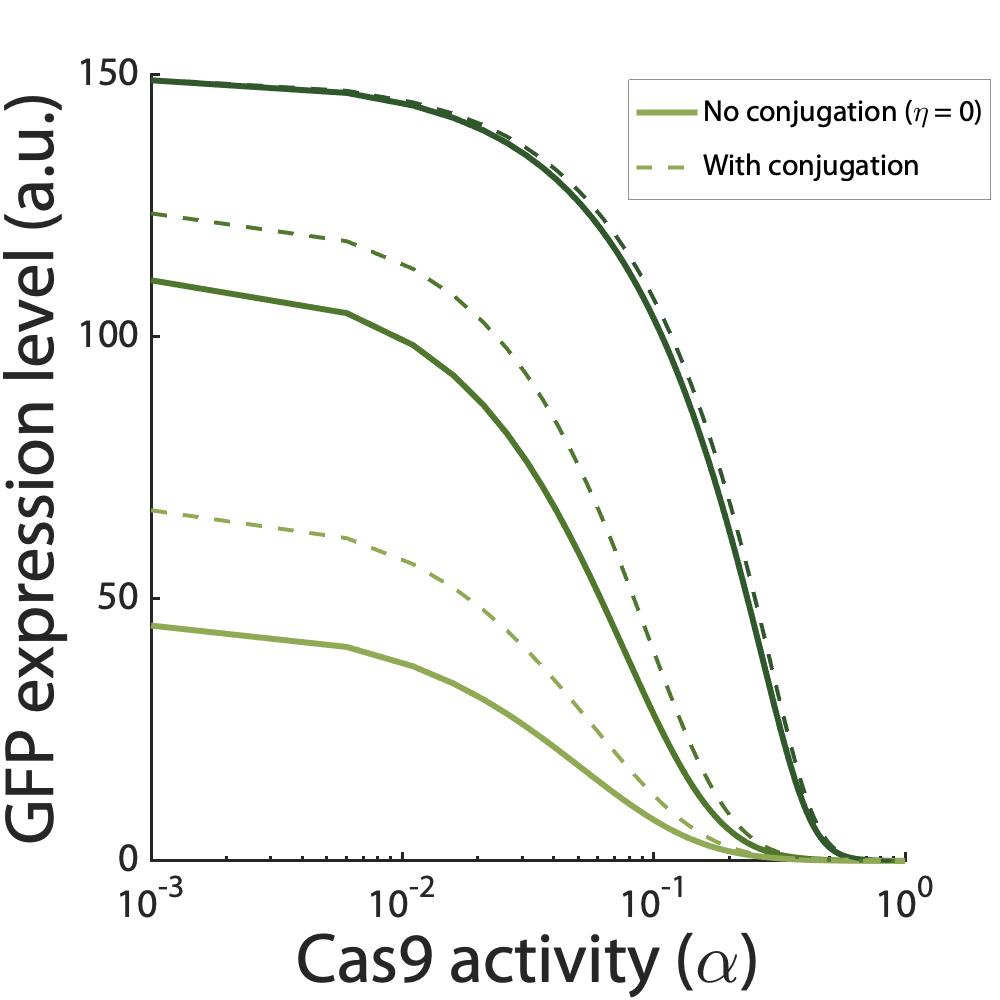

% plot GFP only
% non-dimensionalized parameters used here
% solid line => when no conjugation; dotted line => with conjugation;

global u_s u_p alpha eta delta D gamma d
% define parameter values here
u_s = 1.15; u_p = 1.0; alpha = 0.83; delta = 0.17; eta = 0.05; gamma = 22; d = 0.13; 
alphas = linspace(0.001, 1.5, 300); 
deltas = [0.48, 0.12, 0];

% initialize arrays to save computed values
end_S = []; end_Sp = []; end_G = [];
S_final = zeros([length(deltas), length(alphas)]); 
Sp_final = zeros([length(deltas), length(alphas)]);
G_final = zeros([length(deltas), length(alphas)]);

% color schemes
S_colors = [0, 0.1765, 0.2941; 0, 0.3059, 0.5098; 0, 0.4588, 0.7647;  ];
Sp_colors = [0.4549, 0.1725, 0.0510; 0.7059, 0.2667, 0.0784; 1.0, 0.3765, 0.1098;  ]; 
G_colors = [0.1921, 0.3411, 0.1725; 0.3098, 0.4667, 0.1765; 0.5647, 0.6627, 0.3333];
f_colors = hot(10);

tmax = 24; tspan = [0 tmax]; y0 = [0.001; 0.001; 0]; 

ax = figure(); set(gcf, 'Position',  [10, 10, 500, 500]) ; hold on;
eta = 0;
for j = 1:length(deltas)
    delta = deltas(j);
    for i = 1:length(alphas)
        alpha = alphas(i); [t, y] = pcn_control_gfp(tspan,y0);
        end_S = [end_S; y(end,1)]; end_Sp = [end_Sp; y(end,2)]; end_G = [end_G; y(end,3)];
        Fp(j,i) = y(end,2)/(y(end,1)+y(end,2));
        S_final(j,i) = y(end,1); Sp_final(j,i) = y(end,2); G_final(j,i) = y(end,3);
    end     
    l1 = plot(alphas, end_G, 'linewidth', 3', 'Color', [G_colors(j,:)], 'DisplayName','No conjugation'); 
    end_S = []; end_Sp = []; end_G = [];
end
eta = 0.05; end_S = []; end_Sp = []; end_G = [];
for j = 1:length(deltas)
    delta = deltas(j);
    for i = 1:length(alphas)
        alpha = alphas(i); [t, y] = pcn_control_gfp(tspan,y0);
        end_S = [end_S; y(end,1)]; end_Sp = [end_Sp; y(end,2)]; end_G = [end_G; y(end,3)];
        Fp(j,i) = y(end,2)/(y(end,1)+y(end,2));
        S_final(j,i) = y(end,1); Sp_final(j,i) = y(end,2); G_final(j,i) = y(end,3);
    end     
    l2 = plot(alphas, end_G, '--','linewidth', 2, 'Color', [G_colors(j,:)], 'DisplayName', 'With conjugation'); 
    end_S = []; end_Sp = []; end_G = [];
end
hold off; 
legg = legend([l1,l2],{'No conjugation (\eta = 0)','With conjugation'}, 'Fontsize', 15, 'Location','northeastoutside'); 
newPosition = [0.75 0.8 0.12 0.12]; set(legg,'Position', newPosition);
ax = gca; set(ax,'XScale', 'log');set(gca,'XLim',[1e-3,1e0]);set(ax, 'FontName', 'MyriadPro-Regular')
ax.XAxis.LineWidth = 1.5;  ax.YAxis.LineWidth = 1.5; 
ax.YLabel.String = 'GFP expression level (a.u.)'; ax.XLabel.String = 'Cas9 activity (\alpha)'; 
ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20;ax.XLabel.FontSize = 35; ax.YLabel.FontSize = 35; 

Figure 3A

"suppressed": cutting 

"resting": nothing

"selected": selection

"hyper": selection + induction

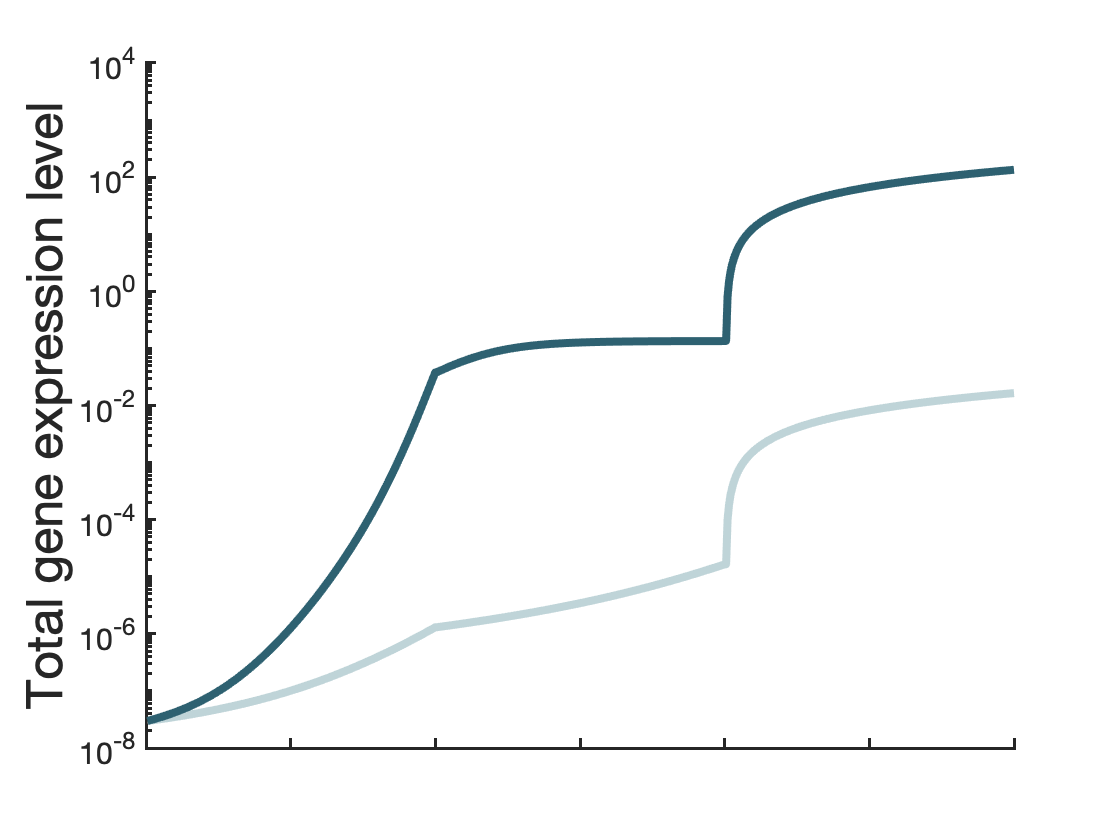


global u_s u_p alpha eta delta gamma d 

% parameters that are constant throughout
u_s = 1.15; u_p = 1.0; d = 0.13; eta = 0.05;
tmax = 24; tspan = [0 tmax]; y0 = [0.00001; 0.00001; 0.0000001];

% initial parameter values 
alpha = 0.83; delta = 0; gamma = 0.022; 
alpha_max = 1.5;

% dynamic range with high basal Cas9 cutting first 

% determine the parameter ranges
alphas = linspace(alpha_max, alpha_max/2, 200); % high basal Cas9 range
deltas = linspace(0, 0.48, 200); % delta (antibiotic selection) range
gammas = linspace(0.022, 22, 200); % inducible promoter (GFP) range

% initialize output arrays
suppressed_leak = zeros(1,length(alphas)); % suppressed -> resting
resting_leak = zeros(1, length(deltas));  % resting -> enriched
hyper_leak = zeros(1, length(gammas)); % enriched -> hyper

% iterate suppressed -> resting
for i=1:length(suppressed_leak)
    alpha = alphas(i);
    [t,y]=pcn_control_gfp(tspan,y0);
    suppressed_leak(i)=y(end,3);
end

% iterate resting -> enriched
for i=1:length(resting_leak)
    delta = deltas(i);
    [t,y]=pcn_control_gfp(tspan,y0);
    resting_leak(i)=y(end,3);
end

% iterate enriched -> hyper
for i=1:length(hyper_leak)
    gamma = gammas(i);
    [t,y]=pcn_control_gfp(tspan,y0);
    hyper_leak(i)=y(end,3);
end

% 
% no Cas9 leakiness dynamic range

% initial parameter values 
alpha = 0.83; delta = 0; gamma = 0.022; 

% initialize output arrays
suppressed = zeros(1,length(alphas)); 
resting = zeros(1, length(deltas));  % resting -> enriched
hyper = zeros(1, length(gammas)); % enriched -> hyper

% iterate suppressed -> resting
alphas = linspace(alpha_max, 0, 200); % no leaky Cas9

for i=1:length(suppressed)
    alpha = alphas(i);
    [t,y]=pcn_control_gfp(tspan,y0);
    suppressed(i)=y(end,3);
end

% iterate resting -> enriched
for i=1:length(resting)
    delta = deltas(i);
    [t,y]=pcn_control_gfp(tspan,y0);
    resting(i)=y(end,3);
end

% iterate enriched -> hyper
for i=1:length(hyper)
    gamma = gammas(i);
    [t,y]=pcn_control_gfp(tspan,y0);
    hyper(i)=y(end,3);
end

% plot dynamic range with high basal Cas9
figure(); hold on;
str = '#BFD4D8'; % high basal
color_leak = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255;
plot([suppressed_leak,resting_leak,hyper_leak], 'LineWidth',4, 'Color',color_leak);
ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5;
ax.YLabel.FontSize = 30; ax.XLabel.FontSize = 30; ax.YAxis.FontSize = 15;ylabel('Total gene expression level', 'FontSize',25);
set(gca,'XTickLabel',[]); ylim([1e-8, 1e4])

% plot no leak Cas9
str = '#2E6171'; % no basal
color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255;
plot([suppressed,resting,hyper], 'LineWidth',4, 'Color',color);

% style
set(gca, 'YScale', 'log'); ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5;
ax.YLabel.FontSize = 30; ax.XLabel.FontSize = 30; ax.YAxis.FontSize = 15;
ylabel('Total gene expression level', 'FontSize',25); set(gca,'XTickLabel',[]); hold off;

Supplementary Figure 9B (left)

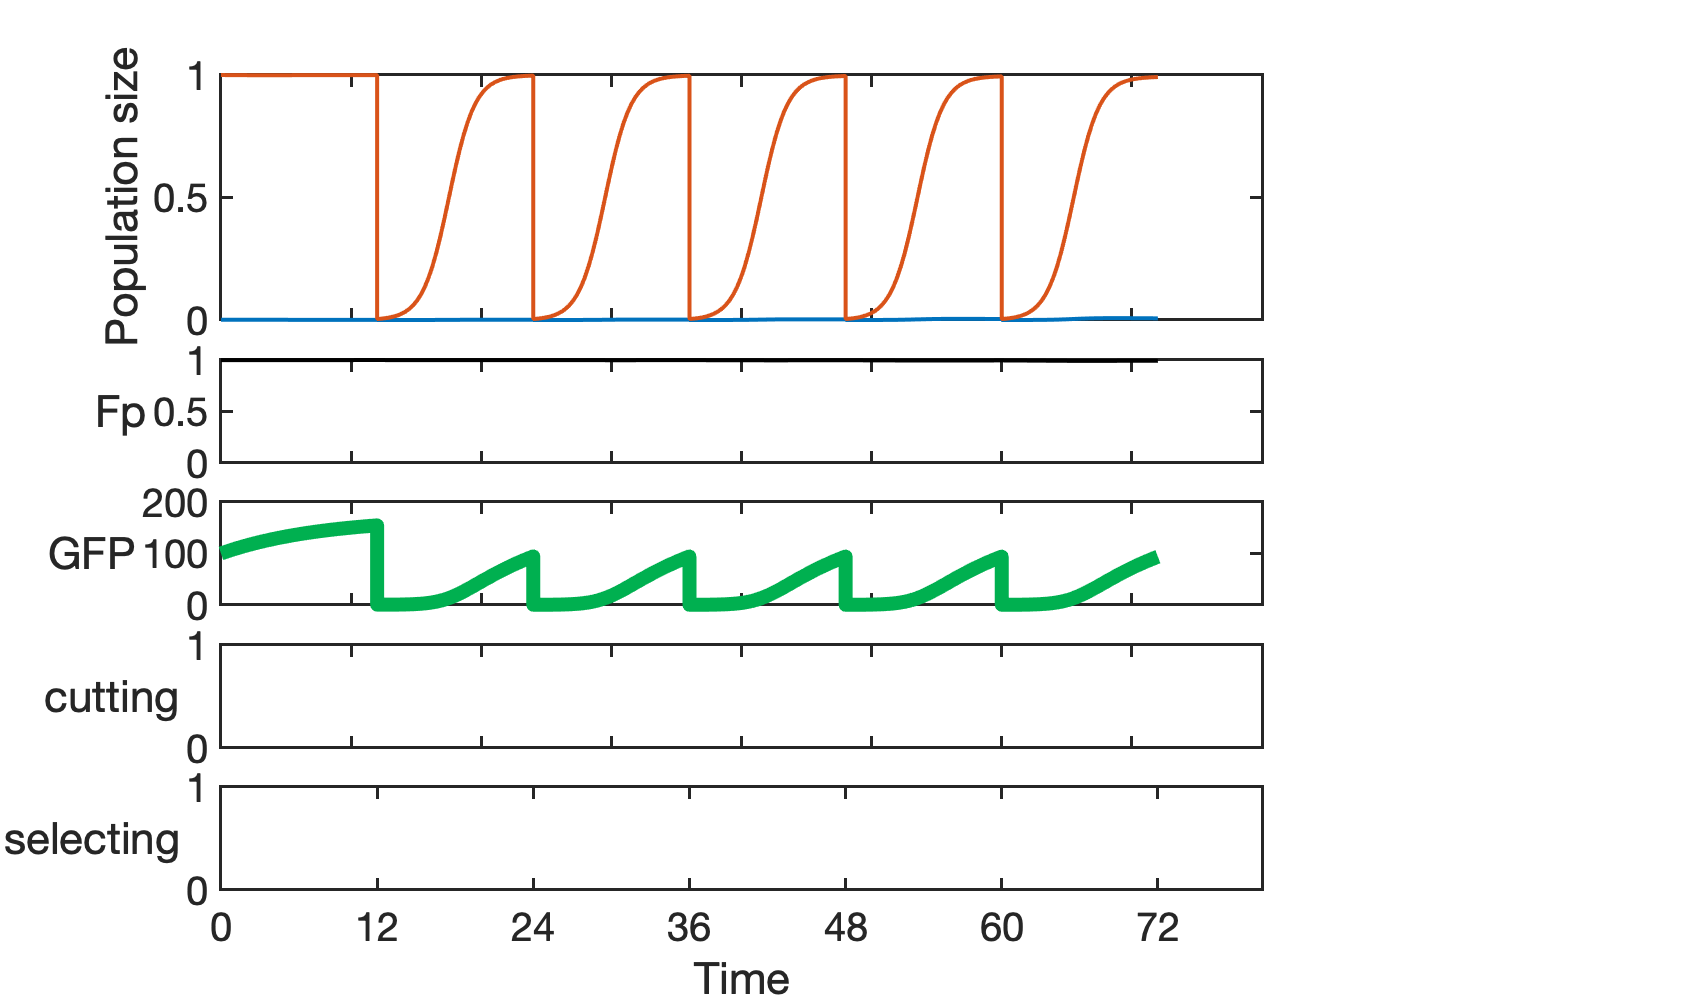

atc = 0; % alpha
kan = 0; % delta
alpha_duration = 0;
[t_s9bl, gfp_s9bl] = periodic_forcing(atc, kan, alpha_duration);

Supplementary Figure 9B (middle)

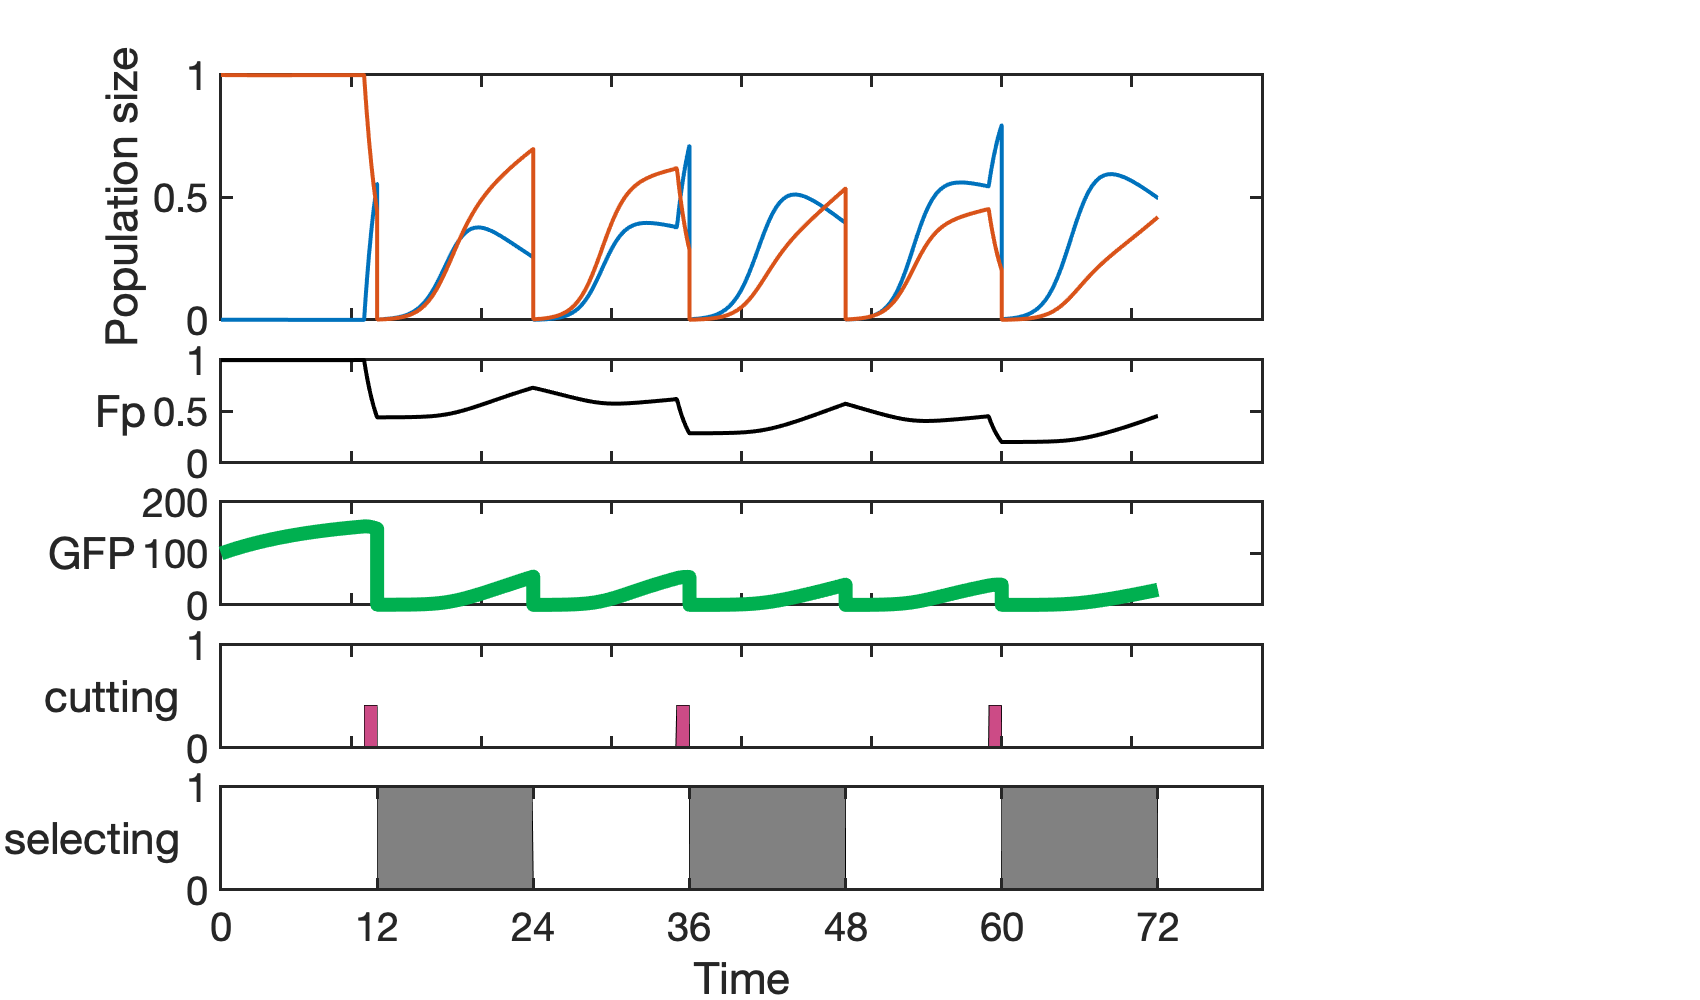

atc = 0.83; % alpha
kan = 0.15; % delta
alpha_duration = 1.0;
[t_s9bm, gfp_s9bm] = periodic_forcing(atc, kan, alpha_duration);

Supplementary Figure 9B (right)

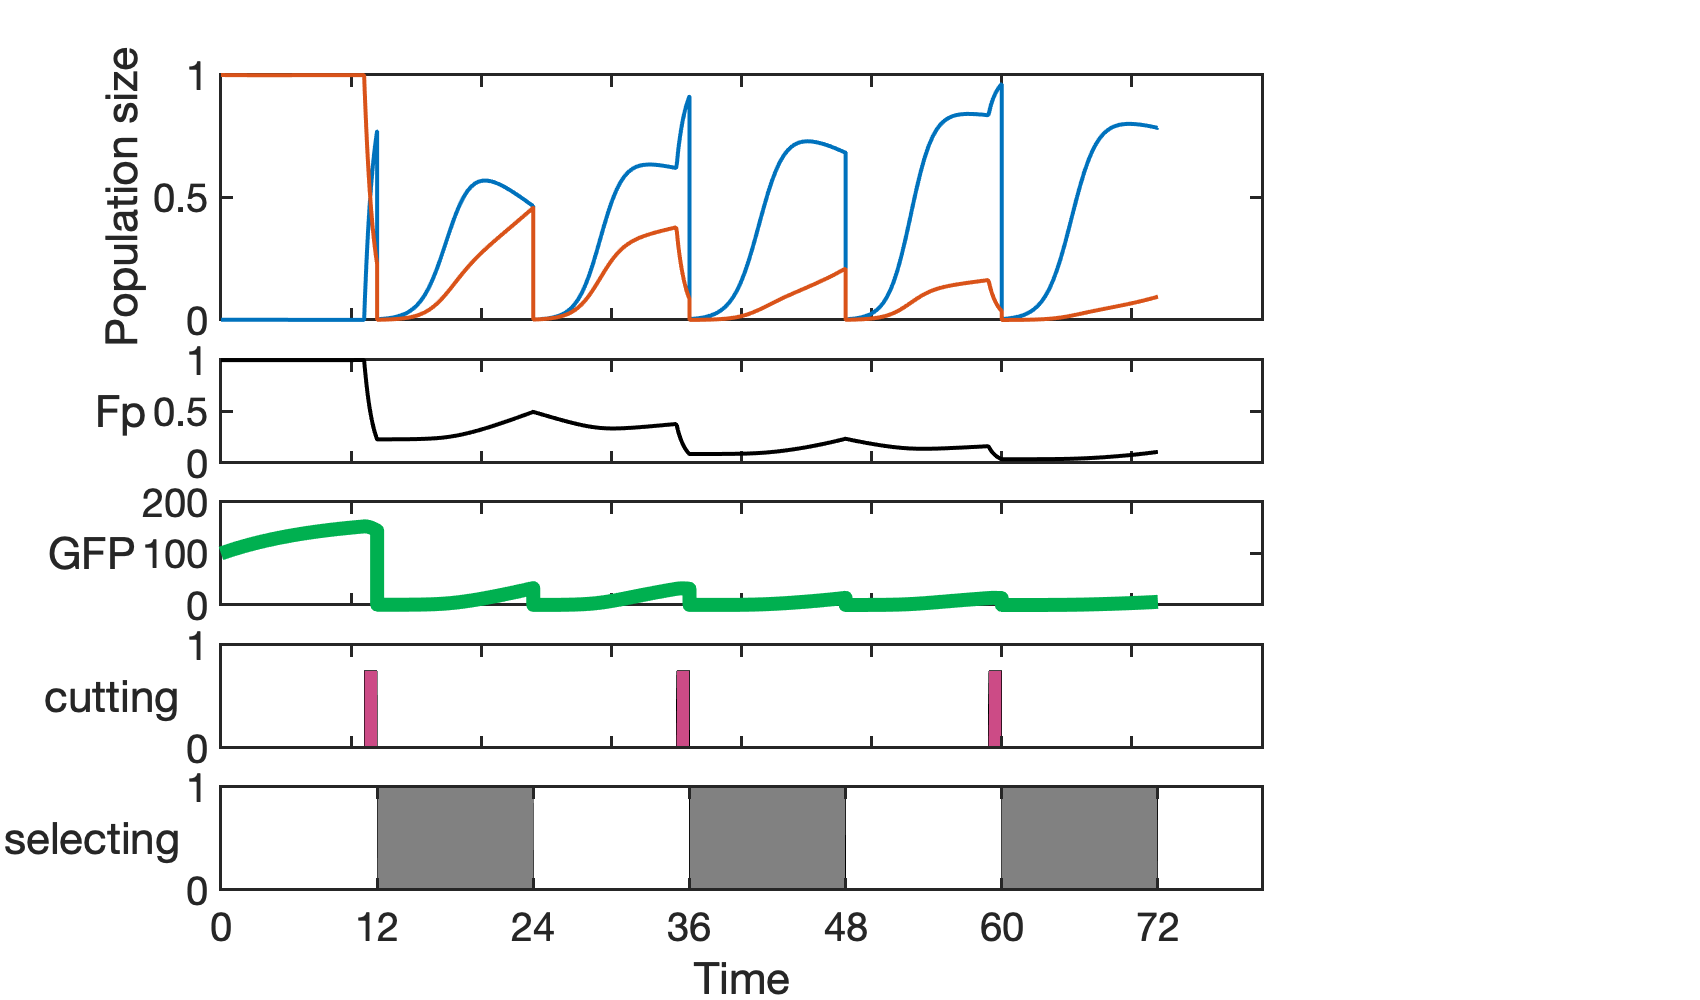

atc = 1.5; % alpha
kan = 0.15; % delta
alpha_duration = 1.0;
[t_s9br, gfp_s9br] = periodic_forcing(atc, kan, alpha_duration);

Figure 4A

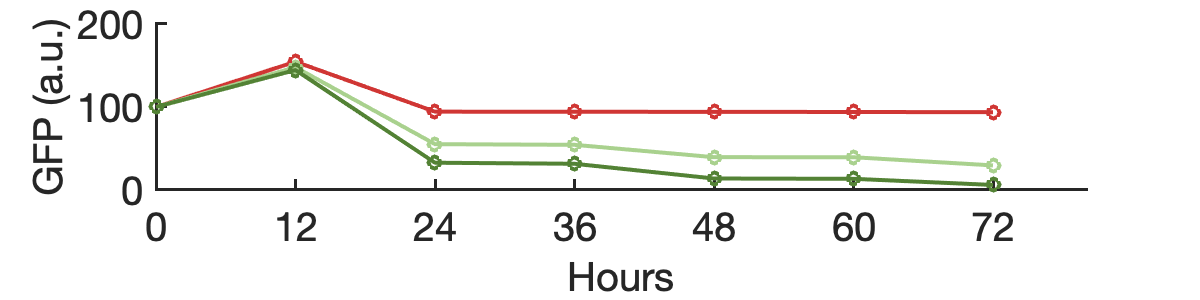

% initiate arrays; store gfp values 
% at 0, 12, 24, 36, 48, 60, and 72 hours
control_group = zeros(7,1);
low_atc_group = zeros(7,1);
high_atc_group = zeros(7,1);
time_points = [0,12,24,36,48,60,72];
for i = 1:length(time_points)
    control_group(i) = gfp_s9bl(find(t_s9bl>=time_points(i),1));
    low_atc_group(i) = gfp_s9bm(find(t_s9bm>=time_points(i),1));
    high_atc_group(i) = gfp_s9br(find(t_s9br>=time_points(i),1));
end

figure(); set(gcf, 'Position', [100, 100, 600, 150]); hold on;
str = '#D03634'; color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255; plot(time_points, control_group, 'Linewidth', 2, 'marker', 'o', 'color', color); 
str = '#A9D18E'; color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255; plot(time_points, low_atc_group, 'Linewidth', 2, 'marker', 'o', 'color', color); 
str = '#538235'; color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255; plot(time_points, high_atc_group, 'Linewidth', 2, 'marker', 'o', 'color', color); 
ylim([0, 200]); ax = gca; xticks([0,12,24,36,48,60,72]);
ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5; ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20; 
xlabel('Hours', "FontSize", 20); ylabel('GFP (a.u.)', 'fontsize', 20);

Supplementary Figure 9C (left)

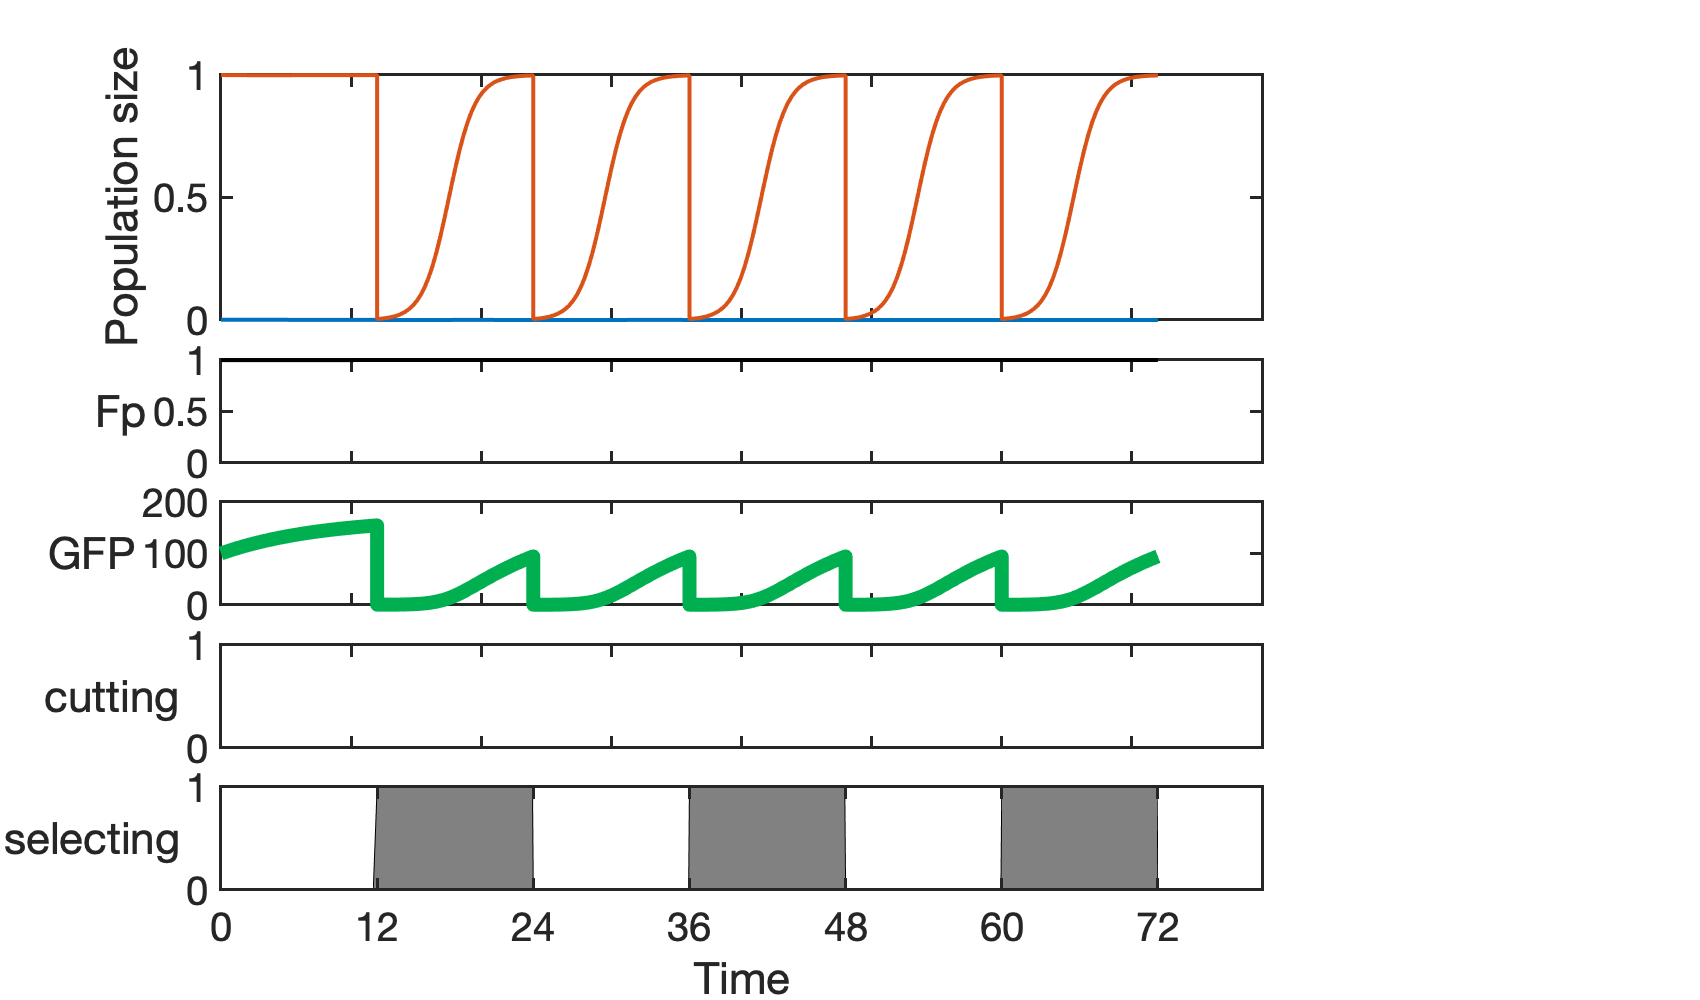

atc = 0; % alpha
kan = 0.15; % delta
alpha_duration = 0;
[t_s9bl, gfp_s9bl] = periodic_forcing(atc, kan, alpha_duration);

Supplementary Figure 9C (middle)

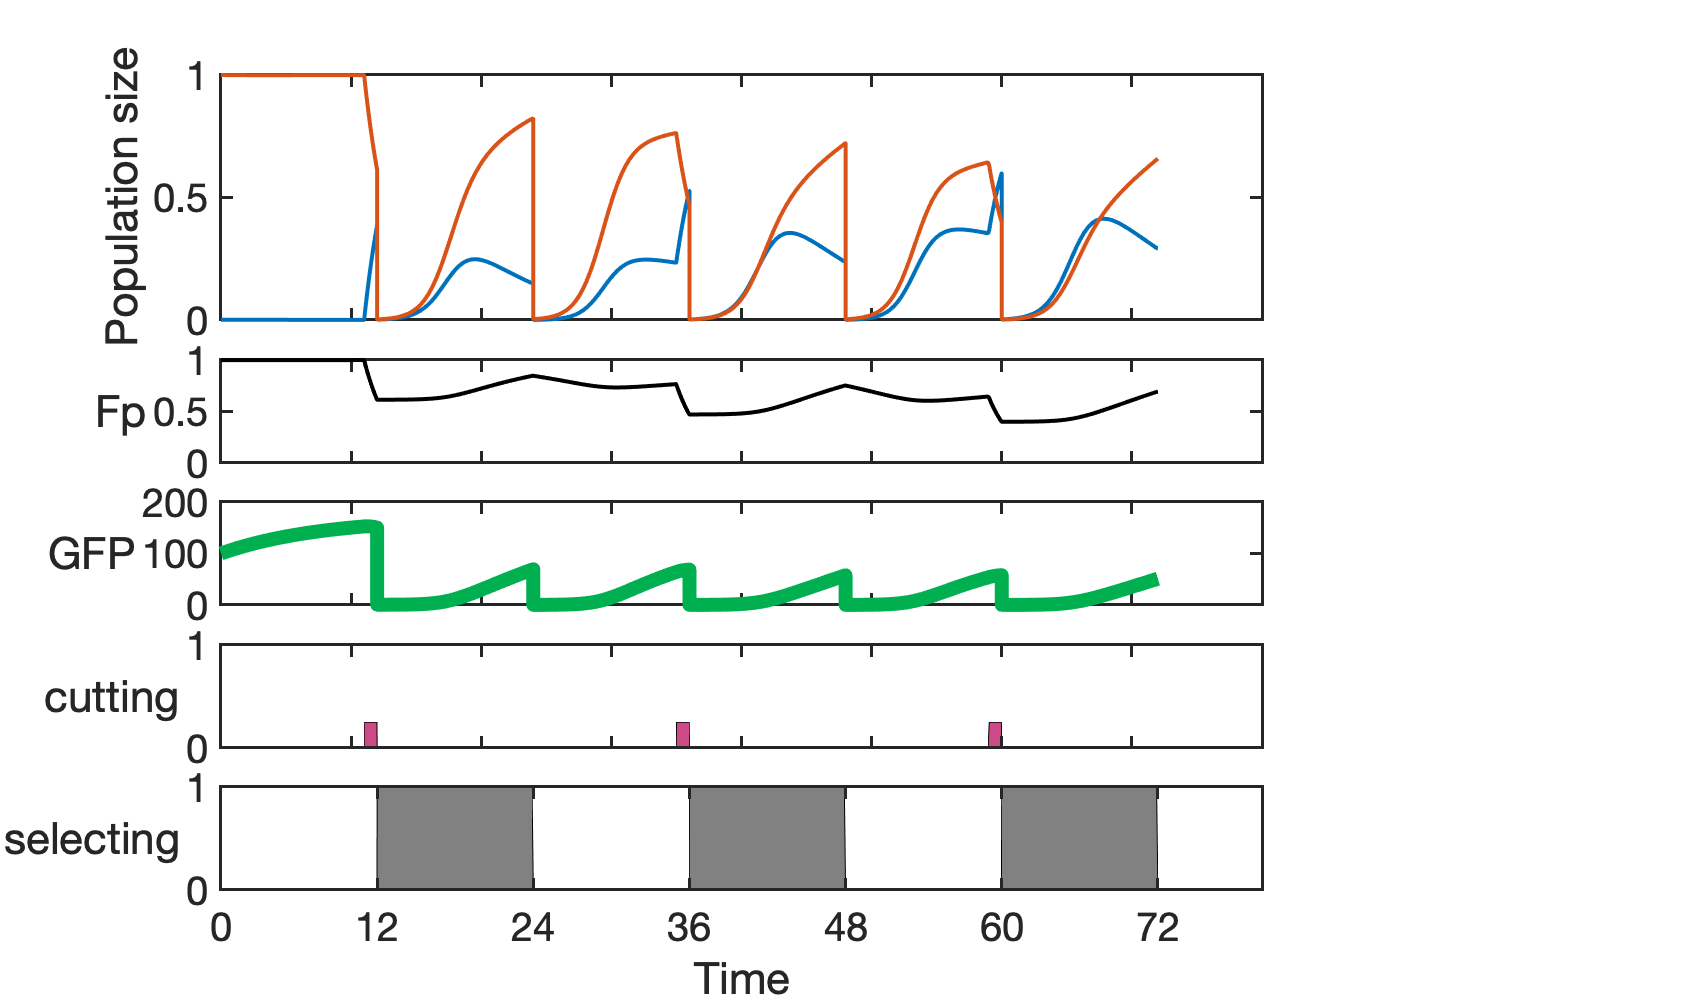

atc = 0.5; % alpha
kan = 0.15; % delta
alpha_duration = 1.0;
[t_s9bl, gfp_s9bl] = periodic_forcing(atc, kan, alpha_duration);

Supplementary Figure 9C (right)

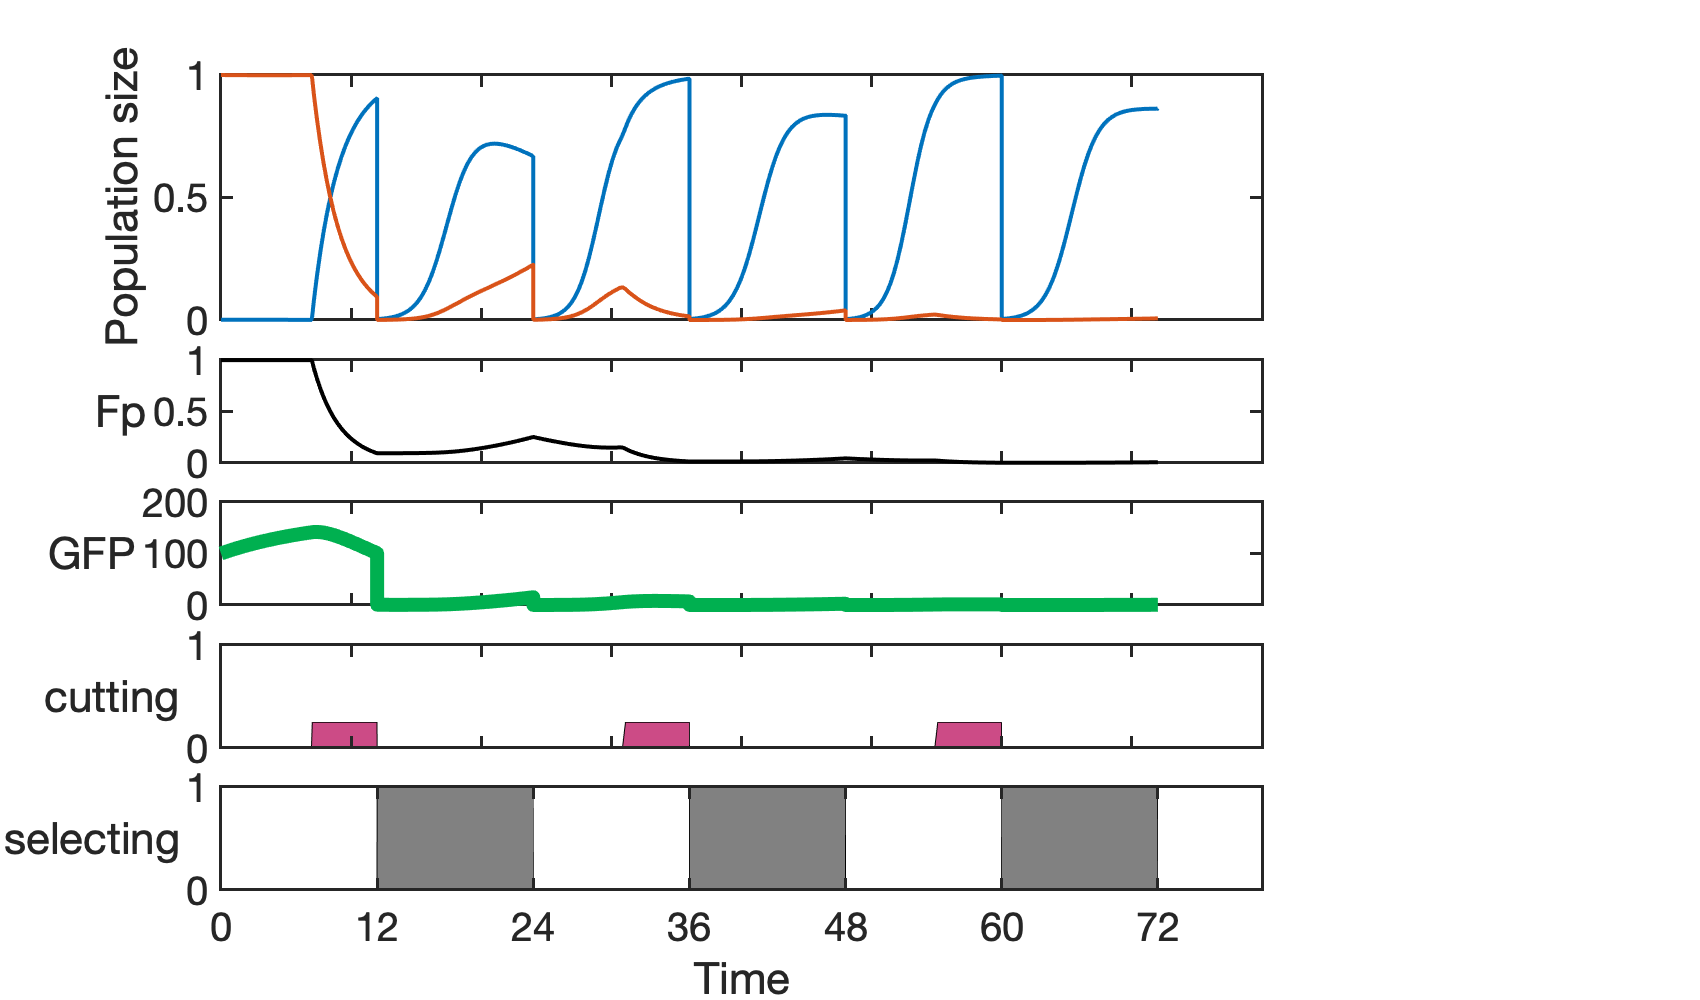

atc = 0.5; % alpha
kan = 0.15; % delta
alpha_duration = 5.0;
[t_s9bl, gfp_s9bl] = periodic_forcing(atc, kan, alpha_duration);

function [t, y] = pcn_control_gfp(tspan, y0)
    options = odeset('NonNegative',[1,2,3]);
    [t,y] = ode45(@eom, tspan, y0, options);
end


function dydt = eom(Time,y)
    global u_s alpha delta eta u_p gamma d
    dydt = [ u_s * y(1) * (1 - (y(1)+y(2))) + alpha * y(2) - delta  * y(1) - eta * y(1) * y(2);
             u_p * y(2) * (1 - (y(1)+y(2))) - alpha * y(2) + eta * y(1) * y(2) ;
             gamma * y(2) - d * y(3);
           ];
end

function [t, y] = s_sp_gfp_pulses(tspan, y0, overall_time, alpha_duration)
    options = odeset('NonNegative', [1, 2, 3]);
    [t, y] = ode45(@(t, y) pulse_eom(t, y, overall_time, alpha_duration), tspan, y0, options);  % Pass overall_time to eom
end

function dydt = pulse_eom(Time, y, overall_time, alpha_duration)
    global u_s u_p alpha eta delta gamma d 
    internal_time = overall_time + Time;
    
    if internal_time >= (12 - alpha_duration) && internal_time < 12
        cutting = 1;
    elseif internal_time >= (36 - alpha_duration) && internal_time < 36
        cutting = 1;
    elseif internal_time >= (60 - alpha_duration) && internal_time < 60
        cutting = 1;
    else 
        cutting = 0;
    end
    
    if internal_time > 12 && internal_time < 24
        killing = 1;
    elseif internal_time > 36 && internal_time < 48
        killing = 1;
    elseif internal_time > 60 && internal_time < 72
        killing = 1;
    else
        killing = 0;
    end
    
    dydt = [u_s * y(1) * (1.0 - (y(1) + y(2))) + alpha * y(2) * cutting - delta * y(1) * killing - eta * y(1) * y(2);
            u_p * y(2) * (1.0 - (y(1) + y(2))) - alpha * y(2) * cutting + eta * y(1) * y(2);
            gamma * y(2) - d * y(3);
           ];
end


function [t, gfp] = periodic_forcing(atc, kan, alpha_duration)
    % output time and gfp 
    
    global u_s u_p alpha eta delta gamma d 
    u_s = 1.15; u_p = 1.0; eta = 0.05; gamma = 22; d = 0.13;
    
    alpha = atc; delta = kan;
    
    alpha_max = 2.0; delta_max = 0.15; % maximum alpha and delta values used for normalization 
    tmax = 72;
    segments = 6;           % Number of segments
    segment_duration = 12;  % Duration of each segment
    y0 = [0.001; 1.0; 100.0]; % start with Fp ~ 1.0
    
    % Initialize variables to store the results
    all_t = [];
    all_y = [];
    overall_time = 0;       % Initialize overall time
    
    % Run the ODE solver for each segment
    for i = 1:segments
        tspan = [segment_duration * (i-1), segment_duration * i];
        [t, y] = s_sp_gfp_pulses(tspan, y0, overall_time, alpha_duration);  % Pass overall_time as an input
        
        % Store the results
        all_t = [all_t; t];
        all_y = [all_y; y];
        
        % Update y0 for the next segment
        y0 = y(end, :) / 250;
        
    end
    
    y = all_y; t = all_t;
    figure('Renderer', 'painters', 'Position', [10 10 850 500]);  
    % plot S and Sp
    subplot(6,5,[1,2,3,4,6,7,8,9]); 
        plot(t, y(:,[1,2]), 'Linewidth', 2); ylabel('Population size', 'FontSize',20); xticklabels([])
        ylim([0 1]); ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5; ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20;
    % plot Fp 
    subplot(6,5,[11,12,13,14]); 
        plot(t, y(:,2)./(y(:,1)+y(:,2)), 'LineWidth',2,'Color','k'); 
        ylabel('Fp', 'fontsize', 20,'rotation',0, 'horizontalAlignment','right', 'VerticalAlignment','middle'); xticklabels([])
        ylim([0 1]); ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5; ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20;
    % plot GFP
    subplot(6,5,[16,17,18,19]); hold on; box on;
        str = '#00B050'; color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255; 
        plot(t, y(:,3), 'linewidth', 7, 'Color',color);  
        ylabel('GFP', 'fontsize', 20,'rotation',0, 'horizontalAlignment','right', 'VerticalAlignment','middle'); xticklabels([])
        ylim([0,200]); ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5; ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20;
    
    gfp = y(:,3);
    
    % compute and plot cutting and selecting (killing)
    x_time = t; cutt = zeros(1, length(x_time)); kill = zeros(1, length(x_time));
        for i=1:length(x_time)
            tt = x_time(i); 
            if tt >= 24 && tt < 48
                tt = tt-24;
            end
            if tt >= 48 && tt < 72
                tt = tt-48;
            end
            if tt >= (12 - alpha_duration) && tt < 12
                cutt(i) = 1;  % Cutting is active from t=11 to t=12
            else
                cutt(i) = 0;  % No cutting
            end
            if tt >= 12 && tt < 24
                kill(i) = 1;  % Killing is active from t=12 to t=24
            else
                kill(i) = 0;  % No killing
            end
        end
    cutt = cutt*alpha/alpha_max; kill = kill*delta/delta_max;
    subplot(6,5,[21,22,23,24]); 
        str = '#CC4B86'; color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255; 
        cut_area = area(x_time, cutt); cut_area.FaceColor = color;
        ylabel('cutting','rotation',0, 'horizontalAlignment','right', 'VerticalAlignment','middle'); xticklabels([]) 
        ylim([0 1]); ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5; ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20;yticks([0,1]); 
    subplot(6,5,[26,27,28,29]); 
        str = '#818181'; color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255; 
        kill_area = area(x_time, kill); kill_area.FaceColor = color; 
        ylabel('selecting','rotation',0, 'horizontalAlignment','right', 'VerticalAlignment','middle'); xticks([0,12,24,36,48,60,72]);xlabel('Time', "FontSize", 20);
        ylim([0 1]); ax = gca; ax.XAxis.LineWidth = 1.5; ax.YAxis.LineWidth = 1.5; ax.XAxis.FontSize = 20; ax.YAxis.FontSize = 20; yticks([0,1]);
end

